## Problem 1

Eric Nguyen

format long e
x0 = 0;
f = @(x) sin(x) - cos(x);
df = @(x) cos(x) + sin(x);
h = zeros(1,12);
for i = 1:12
    h(i) = 10^(-i);
end
h;

### Two-point forward difference formula

a = (f(x0 + h) - f(x0)) ./ h;
a_err = abs(df(x0) - a);
disp(a)

  Columns 1 through 5

     1.048292513688025e+00     1.004983291750139e+00     1.000499833291646e+00     1.000049998333141e+00     1.000004999984760e+00

  Columns 6 through 10

     1.000000500073206e+00     1.000000049433680e+00     1.000000005024759e+00     9.999999717180684e-01     1.000000082740371e+00

  Columns 11 through 12

     1.000000082740371e+00     9.999778782798785e-01



disp(a_err)

  Columns 1 through 5

     4.829251368802501e-02     4.983291750138896e-03     4.998332916459347e-04     4.999833314123237e-05     4.999984760445386e-06

  Columns 6 through 10

     5.000732059556867e-07     4.943368026033568e-08     5.024759275329416e-09     2.828193157444758e-08     8.274037099909037e-08

  Columns 11 through 12

     8.274037099909037e-08     2.212172012150404e-05



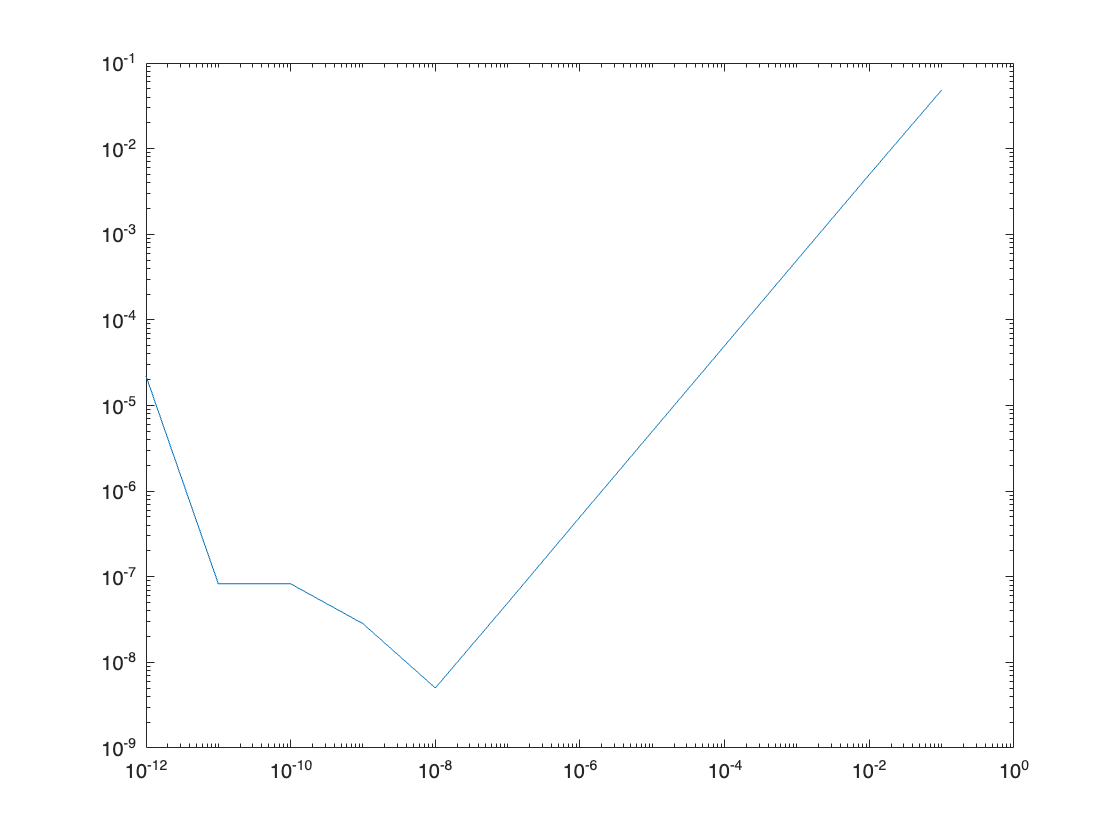

loglog(h, a_err)

The round-off error starts to dominate for $h = 10^{-8}$ using the Two-point forward difference formula.

### Three-point midpoint formula

b = (1./(2.*h)) .* (f(x0 + h) - f(x0 - h));
b_err = abs(df(x0) - b);
disp(b)

  Columns 1 through 5

     9.983341664682821e-01     9.999833334166652e-01     9.999998333333759e-01     9.999999983328900e-01     9.999999999843469e-01

  Columns 6 through 10

     9.999999999732445e-01     9.999999994736442e-01     9.999999994736442e-01     1.000000027229220e+00     1.000000082740371e+00

  Columns 11 through 12

     1.000000082740371e+00     1.000033389431110e+00



disp(b_err)

  Columns 1 through 5

     1.665833531717897e-03     1.666658333476789e-05     1.666666240573988e-07     1.667110005598715e-09     1.565314544649254e-11

  Columns 6 through 10

     2.675548671504657e-11     5.263558477963670e-10     5.263558477963670e-10     2.722921954578794e-08     8.274037099909037e-08

  Columns 11 through 12

     8.274037077704577e-08     3.338943110975379e-05



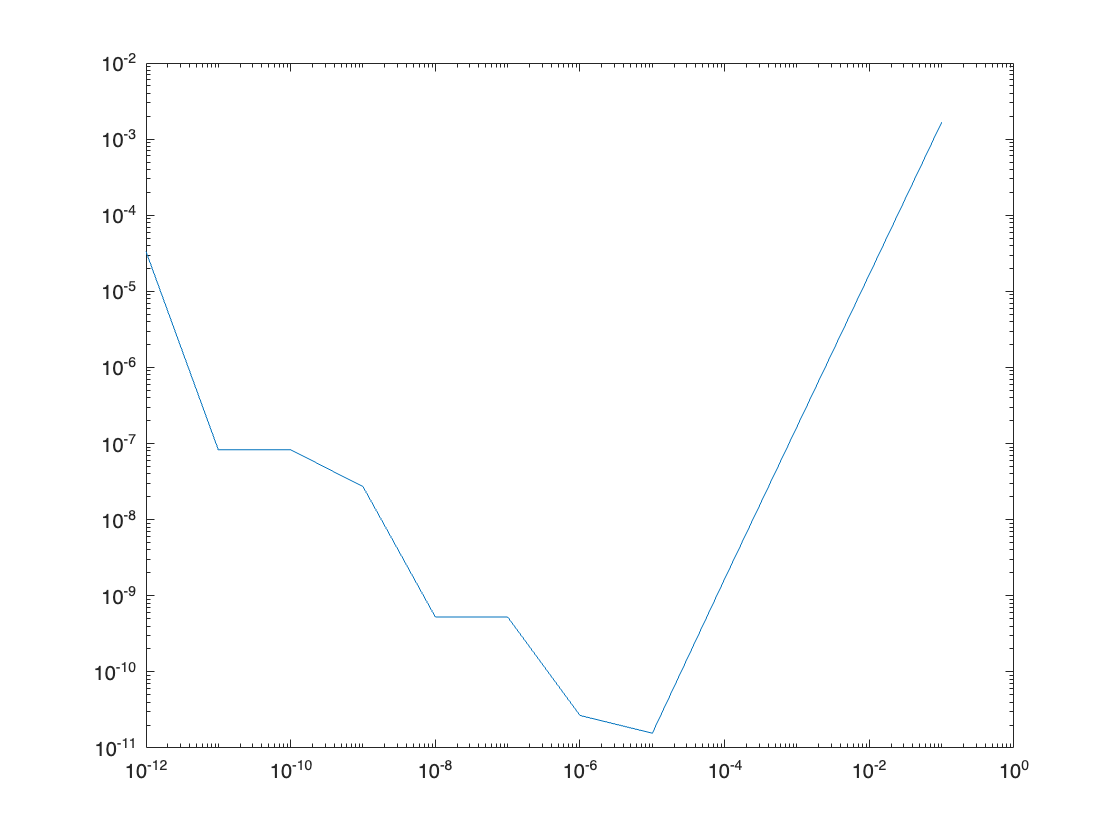

loglog(h, b_err)

The round-off error starts to dominate for $h = 10^{-5}$ using the Three-point midpoint formula.